# A6

## 1. Lyapunov functions

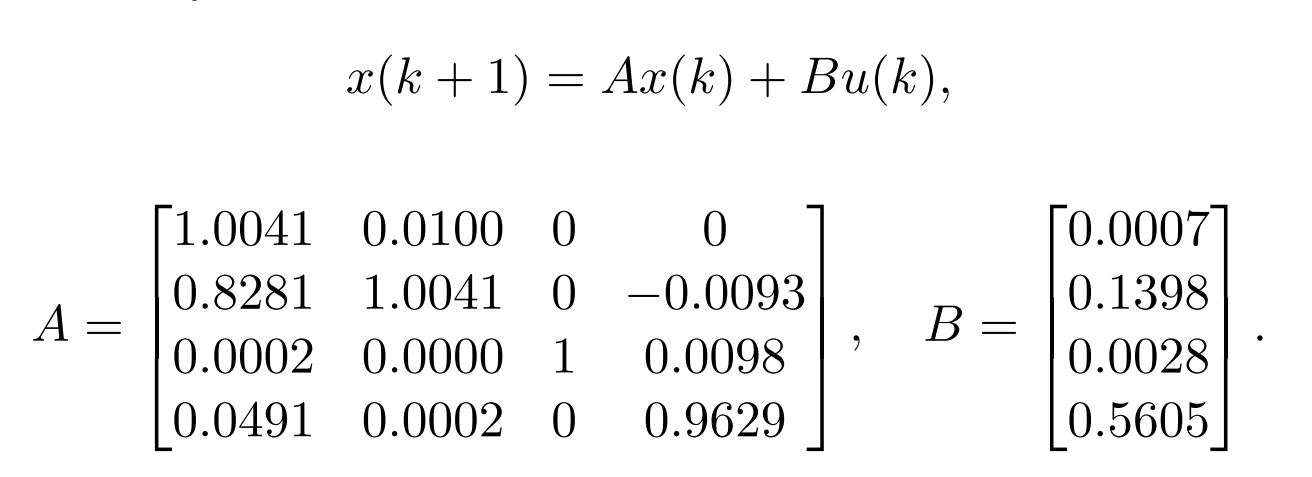

clc
clear
A = [1.0041 0.0100 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9629];
B = [0.0007;
    0.1398;
    0.0028;
    0.5605];

(a) Assume u(k) = 0, Lyapunov function

and Lyapunov equation

Assume , find Q. 

S = eye(4);
Q = S-A'*S*A

Q =    -0.6964   -0.8415   -0.0002   -0.0396
   -0.8415   -0.0083         0    0.0091
   -0.0002         0         0   -0.0098
   -0.0396    0.0091   -0.0098    0.0726



[~, flagS] = chol(S); % flag = 0, S symmetric positive definite
if ~flagS
    [~, flagQ] = chol(Q);
    if ~flagQ
        disp("Q is positive definite. System is stable.")
    else
        disp("Q is not positive definite. System is not stable.")
    end
else
    disp("S is not symmetric positive definite.")
end

Q is not positive definite. System is not stable.



if issymmetric(Q)
    if all(eig(Q)>0)
        e = eig(Q);
        disp("Q is symmetric and all eigen values are positive. System is stable.");
    else
        disp("Not all eigen values of Q are positive. Not stable.");
    end
else
    disp("Q is not symmetric. Not stable.")
end

Not all eigen values of Q are positive. Not stable.



eigenA = eig(A);
if all(abs(eigenA) < 1)
    disp("All eigenvalues of A is smaller than 1, system stable.")
else
    disp("Not all eigenvalues of A are smaller than 1, system not stable")
end

Not all eigenvalues of A are smaller than 1, system not stable


(b) consider u(k)=-Kx(k)

closed-loop system is 


$$x(k+1)=(A-BK)x(k) = A_k x(k) \\
A_k^T S A_k-S=-Q$$


S = eye(4);
K = [114.3879 12.7189 -1.2779 -1.5952];
Ak = A-B*K;
Q = S-Ak'*S*Ak

Q = 1.0e+03 *

   -4.3342   -0.4685    0.0489    0.1222
   -0.4685   -0.0504    0.0053    0.0134
    0.0489    0.0053   -0.0006   -0.0014
    0.1222    0.0134   -0.0014   -0.0025


[~, flagS] = chol(S); % flag = 0, S symmetric positive definite
if ~flagS
    [~, flagQ] = chol(Q);
    if ~flagQ
        disp("Q is positive definite. System is stable.")
    else
        disp("Q is not positive definite. System is not stable.")
    end
else
    disp("S is not symmetric positive definite.")
end

Q is not positive definite. System is not stable.



if issymmetric(Q)
    e = eig(Q)
    if all(eig(Q)>0)
        disp("Q is symmetric and all eigen values are positive. System is stable.");
    else
        disp("Not all eigen values of Q are positive. Not stable.");
    end
else
    disp("Q is not symmetric. Not stable.")
end

e = 1.0e+03 *

   -4.3889
   -0.0000
    0.0002
    0.0010


Not all eigen values of Q are positive. Not stable.



eigenAk = eig(Ak)

eigenAk =    0.1894 + 0.0000i
   0.9156 + 0.0101i
   0.9156 - 0.0101i
   0.9901 + 0.0000i


abs(eigenAk)

ans =     0.1894
    0.9156
    0.9156
    0.9901


if all(abs(eigenAk) < 1)
    disp("All eigenvalues of A is smaller than 1, system stable.")
else
    disp("Not all eigenvalues of A are smaller than 1, system not stable")
end

All eigenvalues of A is smaller than 1, system stable.


(c) , find S

S = dlyap(Ak',Q)

S =     1.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000    1.0000


if issymmetric(S)
    e = eig(S)
    if all(eig(S)>0)
        disp("S is symmetric and all eigen values are positive. System is stable.");
    else
        disp("Not all eigen values of S are positive. Not stable.");
    end
else
    disp("S is not symmetric. Not stable.")
end

e =     1.0000
    1.0000
    1.0000
    1.0000


S is symmetric and all eigen values are positive. System is stable.


## 2.Stability with receding horizon control

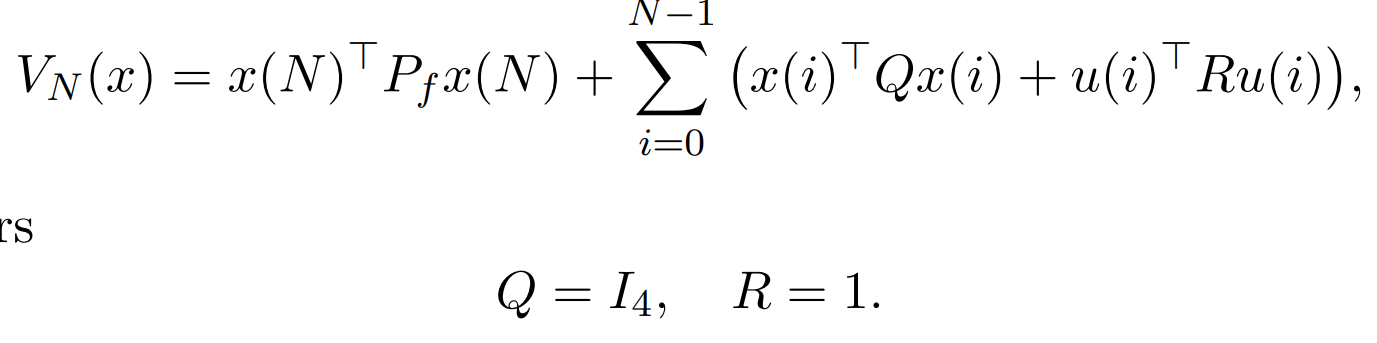

clc
clear
A = [1.0041 0.0100 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9629];
B = [0.0007;
    0.1398;
    0.0028;
    0.5605];
Q = eye(4);
R = 1;

(a) What is the effect of Q  when N=1?

If N = 1, K is computered always by $P_f $, thus Q won't effect the stability

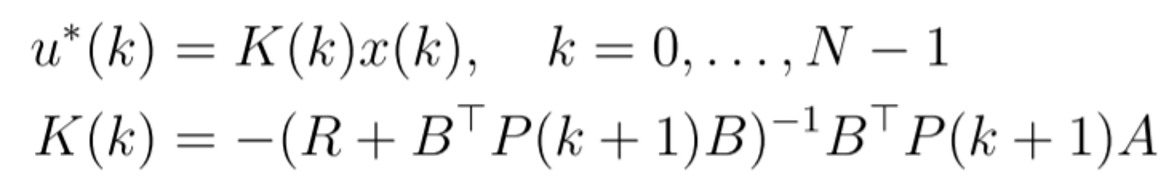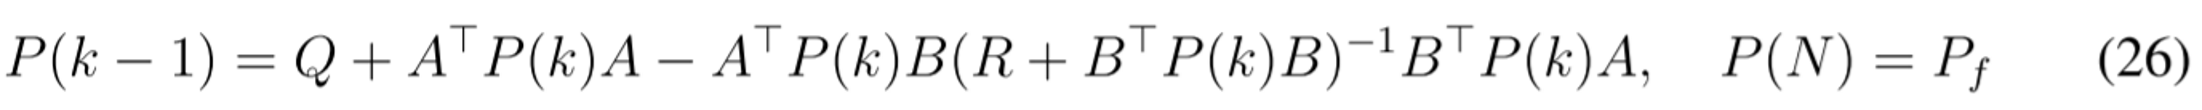

(b) With $P_f=Q$, find the shortest N and corresponding K, such that the RHC stailize the system

Pf = Q;
for N = 1:50
    [P0,K] = DP(A,B,Pf,Q,R,N);
    Ak = A-B*K;
    if all(abs(eig(Ak))<1)
        disp("The shortest N is: ")
        disp(N);
        disp("The corresponding gain K is")
        disp(K);
        break;
    end
end

The shortest N is: 


    38



The corresponding gain K is


   45.6628    5.1672   -0.0068   -0.3898



(c) Verify whether VN (x) is a Lyapunov function for the closed-loop system with the feed-back gain in b) and interpret the result

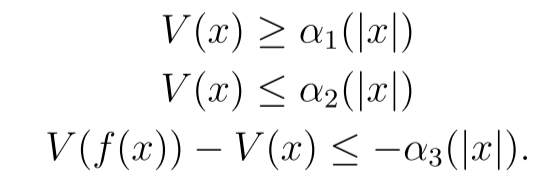

Qc = Ak'*Pf*Ak-Pf+Q+(-K'*B'*R*-B*K)

Qc = 1.0e+03 *

    1.3802    0.1512   -0.0003   -0.0364
    0.1512    0.0174   -0.0000   -0.0041
   -0.0003   -0.0000    0.0010    0.0000
   -0.0364   -0.0041    0.0000    0.0014


[~,flag] = chol(-Qc)

flag = 1

if ~flag
    disp("V is the Lyapunov function")
else
    disp("V is not the Lyapunov function")
end

V is not the Lyapunov function


(d) Find a Pf for which the system is stable for any N ≥ 1. Consider this Pf and N =1, Q = I4 , R = 1 and find the corresponding feedback gain K that minimizes the cost function VN (x). Verify whether VN (x) is a Lyapunov function for the new closed-loop system.

Pf = dare(A,B,Q,R)

Pf = 1.0e+04 *

    4.8730    0.5323   -0.1038   -0.1154
    0.5323    0.0587   -0.0114   -0.0127
   -0.1038   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


N = 1;
[P0,K] = DP(A,B,Pf,Q,R,N);
Ak = A-B*K;
Qc = Ak'*Pf*Ak-Pf+Q+(-K'*B'*R*-B*K)

Qc = 1.0e+03 *

   -3.0579   -0.3396    0.0313    0.0407
   -0.3396   -0.0377    0.0035    0.0045
    0.0313    0.0035   -0.0003   -0.0004
    0.0407    0.0045   -0.0004   -0.0005


[~,flag] = chol(-Qc)

flag = 0

if ~flag
    disp("V is the Lyapunov function")
else
    disp("V is not the Lyapunov function")
end

V is the Lyapunov function


## 3. Receding horizon controller example

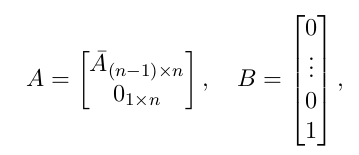

## 4. Stability for constrained systems

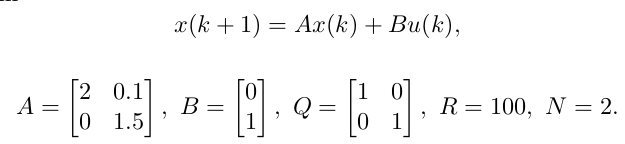

terminal constraint

input constraint

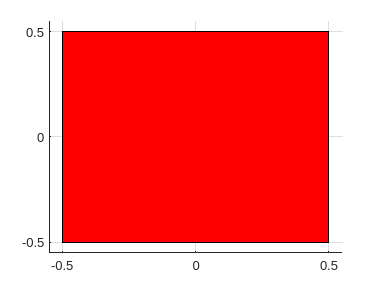

clc
clear

A = [2 0.1;0 1.5];
B = [0;1];
Q = [1 0;0 1];
R = 100;
N = 2;

model = LTISystem('A', A, 'B',B);
% model.x.min = [-0.5; -0.5];
% model.x.max = [ 0.5;  0.5];
model.u.min = -1;
model.u.max =  1;

% X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

C = eye(2);
Xf_constraint =Polyhedron('A',[C;-C],'b',[0.5;0.5;0.5;0.5]); 
model.x.with('terminalSet');
model.x.terminalSet = Xf_constraint;
figure
plot(Xf_constraint)

title("Xf constraints")

Find the largest control invariant set as the system's terminal set

Cinf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...
Iteration 33...
Iteration 34...
Iteration 35...
Iteration 36...
Iteration 37...
Iteration 38...
Iteration 39...
Iteration 40...
Iteration 41...
Iteration 42...
Iteration 43...
Iteration 44...
Iteration 45...
Iteration 46...
Iteration 47...
Iteration 48...
Iteration 49...
Iteration 50...
Iteration 51...
Iteration 52...
Iteration 53...
Iteration 54...
Iteration 55...
Iteration 56...
Iteration 57...


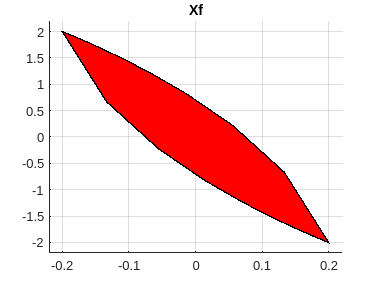

Xf = Cinf;
model.x.with('terminalSet');
model.x.terminalSet = Xf;
figure
plot(Xf)
title("Xf")

Find its N-step backward reahable set $X_0$

XN = Xf;
for i=1:N
    back_XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = back_XN;
end
X0 = XN;

Init condition

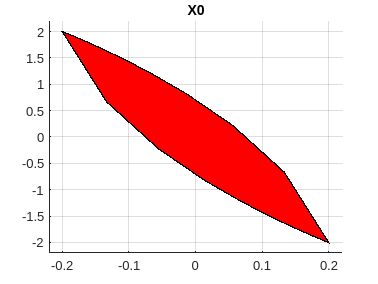

x0 = [-0.1;1.3];
figure
clf
plot(X0)
title("X0")

figure
plot(Xf)
title("Xf")

Find the closed-loop trajectory using MPC when terminal penalty is:


$$P_f=I_2$$


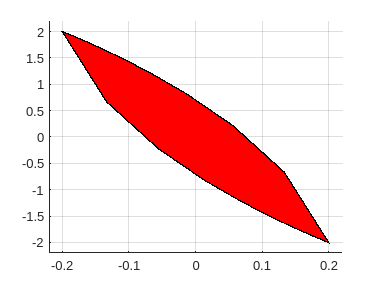

Nsim = 10;

Pf = eye(2);
model.x.with('terminalPenalty');
model.x.terminalPenalty = QuadFunction(Pf);

mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);
data  = loop.simulate(x0, Nsim);

figure
clf; 
hold on;
% plot(X0)
plot(Xf)

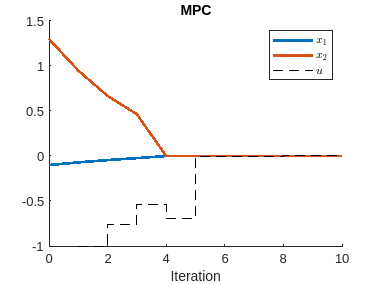


figure
hold on
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')

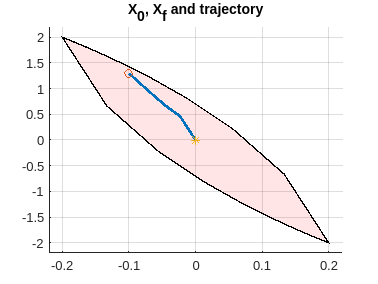


figure
hold on
plot(Xf, 'alpha', 0.1)
plot(data.X(1,:),data.X(2,:), 'Linewidth', 2)
scatter(x0(1), x0(2), 'o')
scatter(data.X(1,end), data.X(2,end), '*')
title('X_0, X_f and trajectory')

$P_f $ as the Riccati solution

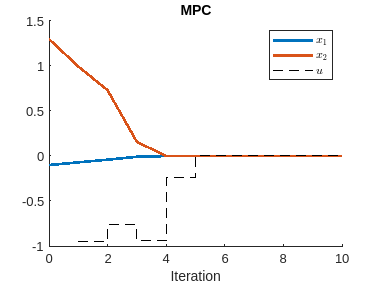

Pf = dare(A,B,Q,R);
model.x.terminalPenalty = QuadFunction(Pf);

mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);
data  = loop.simulate(x0, Nsim);

figure
clf; 
hold on;
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')

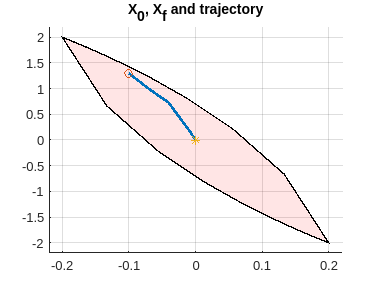


figure
hold on
plot(Xf, 'alpha', 0.1)
plot(data.X(1,:),data.X(2,:), 'Linewidth', 2)
scatter(x0(1), x0(2), 'o')
scatter(data.X(1,end), data.X(2,end), '*')
title('X_0, X_f and trajectory')

function [P0,K] = DP(A,B,Pf,Q,R,N)
    P = cell(1,N+1);
    P{N+1} = Pf;
    for i = N+1:-1:2
        P{i-1} = Q + A'*P{i}*A - A'*P{i}*B*inv(R + B'*P{i}*B)*B'*P{i}*A;
    end
    K = inv(R+B'*P{2}*B)*B'*P{2}*A;
    P0 = P{1};
end